**From the sample EEG data of the course, compute the short-time FFT at each electrode and make topographical maps of theta band (around 6 Hz) power and alpha-band (around 10 Hz) power at 150 ms and 700 ms.**

clear all;clc,clf
load sampleEEGdata
STFT=hardcode_STFT(EEG,EEG.srate,200,50); % (data,srate,window size,overlap %)

targetRows = 64

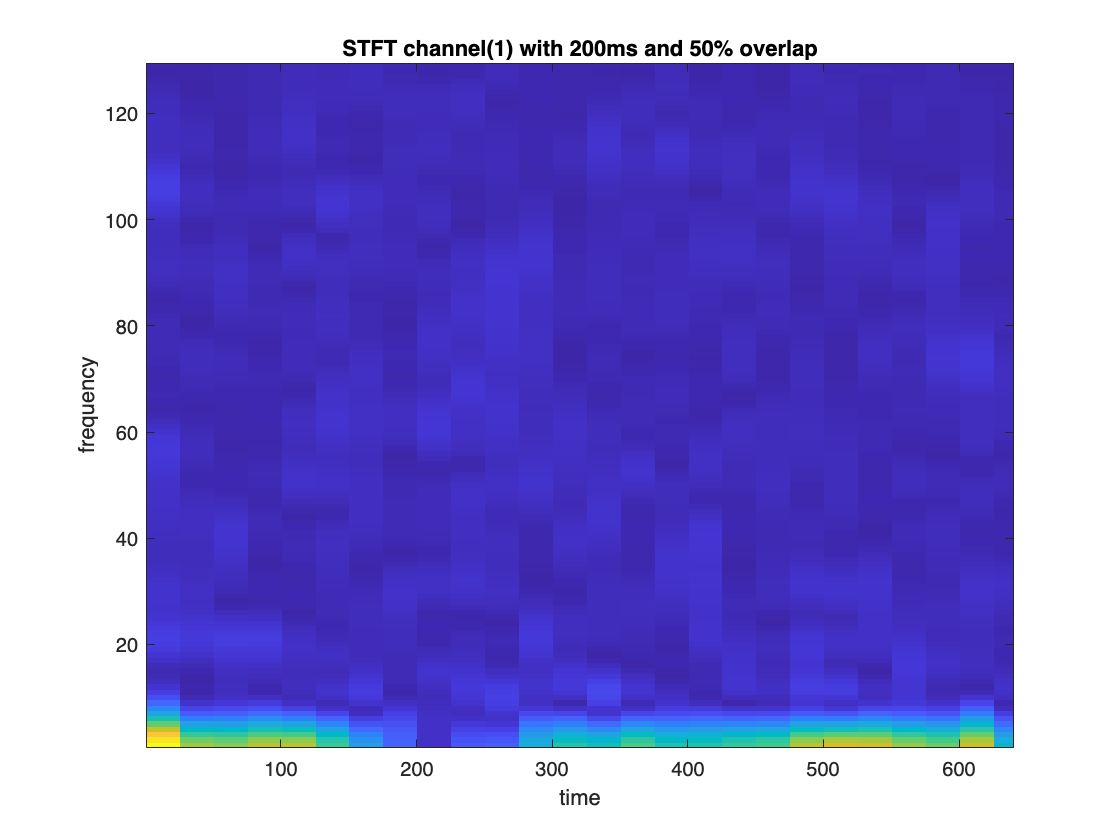

imagesc(abs(flip(STFT{1},1)))
axis xy
title("STFT channel(1) with 200ms and 50% overlap")
xlabel("time")
ylabel("frequency")

pathToAdd = genpath("/Users/erfanmohammadi/Documents/MATLAB/eeglab2023.0");
addpath(pathToAdd);

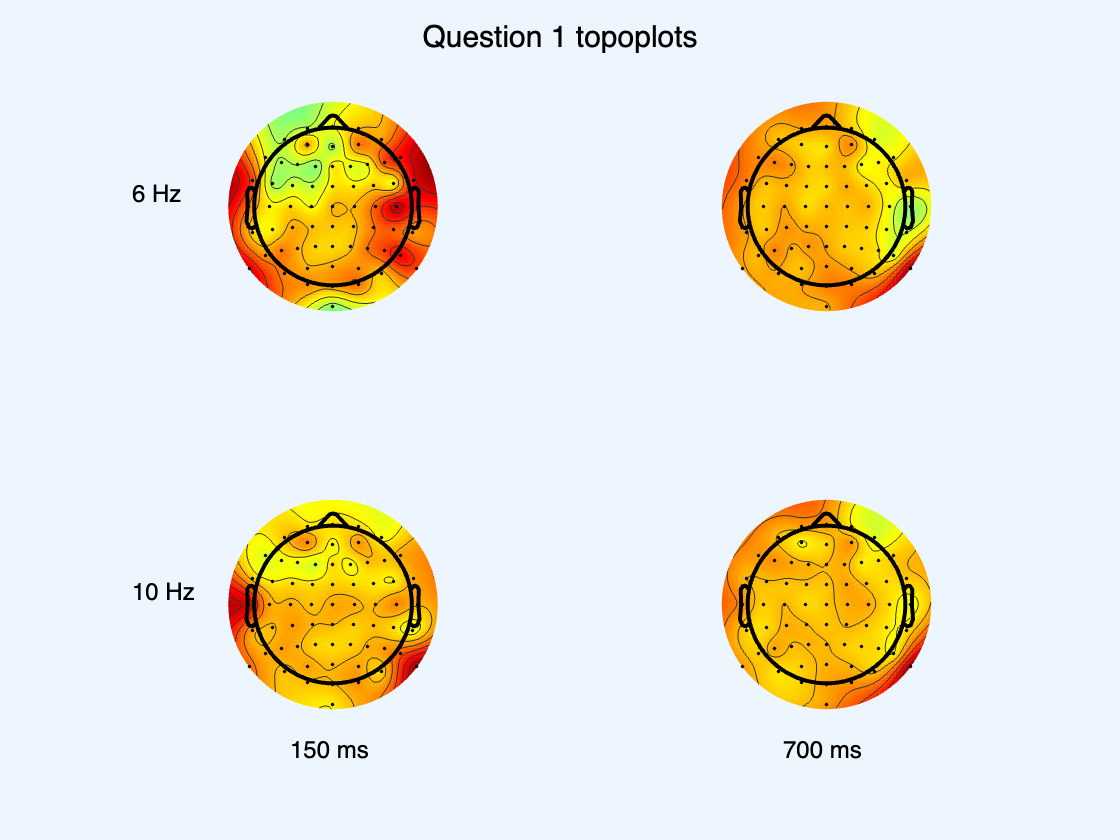

clf
% Create the subplots
subplot(2,2,1)
topoplot((abs(topoplot_calculation(STFT,EEG.srate,6,150))),EEG.chanlocs);
text(-0.2, 0.55, '6 Hz', 'Units', 'normalized');

subplot(2,2,2)
topoplot((abs(topoplot_calculation(STFT,EEG.srate,6,700))),EEG.chanlocs);

subplot(2,2,3)
topoplot((abs(topoplot_calculation(STFT,EEG.srate,10,150))),EEG.chanlocs);
text(-0.2, 0.55, '10 Hz', 'Units', 'normalized');
text(0.35, 0.0, '150 ms', 'Units', 'normalized');

subplot(2,2,4)
topoplot((abs(topoplot_calculation(STFT,EEG.srate,10,700))),EEG.chanlocs);
text(0.35, 0.0, '700 ms', 'Units', 'normalized');
sgtitle("Question 1 topoplots")

**Compute power over time at that electrode and that frequency using complex wavelet convolution, filter-Hilbert, and the short-time FFT.**

**Plot the results of these three time-frequency decomposition methods in different subplots of one figure. Note that the scaling might be different because no baseline normalization has been applied. **

clear;
close all;
clc;
load sampleEEGdata.mat
channel2plot   = 'F1';

chan2useidx = strcmpi(channel2plot,{EEG.chanlocs.labels});

wavelet=hardcode_wavelet(EEG,chan2useidx,10,7) ; %order=7

hilbert=hardcode_hilbert(EEG,chan2useidx,9,11,0.3); %lower_filter_bound  upper_filter_bound  transition_width

STFT=hardcode_STFT(EEG,EEG.srate,300,98);

targetRows = 64

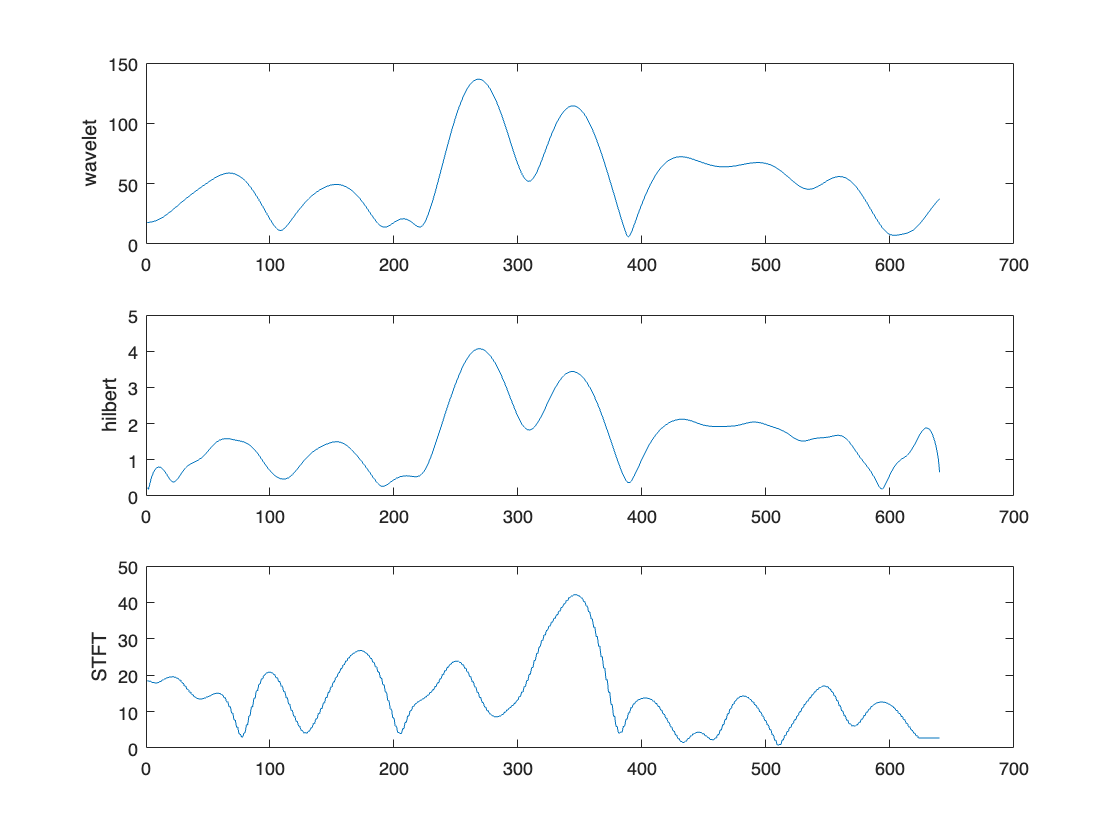



subplot(3,1,1)
plot(abs(wavelet))
ylabel("wavelet")
subplot(3,1,2)
plot(abs(hilbert))
ylabel("hilbert")
subplot(3,1,3)
plot(abs(STFT{chan2useidx}(10,:)))
ylabel("STFT")

This plot shows three algorithms used for power calculation. We can observe that the Hilbert and wavelet methods produce similar results because I attempted to adjust the number of cycles and the transient zone of the Hilbert filter (as we learned previously) at the same frequency (10 Hz). However, the STFT result differs from the Hilbert and wavelet methods.

It is evident that to achieve temporal smoothing similar to the wavelet in the STFT, we should increase the window size and overlap of the STFT. Therefore, I chose an overlap of 98% and a window size of 300 ms, but we can already notice some differences in the results.

## **Hard code:**

function data_topoplot=topoplot_calculation(STFT,srate,freq,times)
for i=1:length(STFT)
    time_samp = round(times/(1000/srate));
    data_topoplot(i)=mean(STFT{i}(freq-2:freq+2,time_samp));
end
end

function wavelet=hardcode_wavelet(EEG,channel,f,n)
data=EEG.data;
srate=EEG.srate;
time=-1:1/srate:1;
sinwaves=exp(1i*2*pi*time.*f);
s=n./(2*pi.*f);
gaussi=exp(-0.5*(time./s').^2);
wavelet=sinwaves.*gaussi;
electrode=EEG.data(channel,:,1);
wavelet=conv(electrode,wavelet,"same");  
end

function STFT=hardcode_STFT(EEG,srate,window_size_ms,overlap)
EEG = (EEG.data(:,:,1));
real_length=size(EEG,2);
% Your original matrix (64x640)
targetRows=size(EEG,1)
targetColumns = 700;
% Create the zero-padded matrix
zeroPaddedMatrix = zeros(targetRows, targetColumns);
zeroPaddedMatrix(:, 1:640) = EEG; 
EEG=zeroPaddedMatrix;

% zeroPaddedMatrix now contains your original data with zero-padding
window_size_samp = round(window_size_ms/(1000/srate));
without_overlap=window_size_samp-round((window_size_samp/100)*overlap);
overlap_sampl=window_size_samp-without_overlap;

for i=1:size(EEG,1)
signal=(EEG(i,:));
condition="start";
start=1;
stft_result=[];
loop_fft_before=[];
window_size_samp = round(window_size_ms/(1000/srate));
while start<length(signal)

    try 
        try
        loop_fft_before=stft_result(:,start+1)';
        
        catch
        end
        loop_window=signal(start:start+window_size_samp);
        taperr=hann(length(loop_window));
        loop_window=loop_window.*taperr';
        loop_fft=fft(loop_window,srate);
        loop_fft=loop_fft(ceil(srate/2):end);
        try
        stft_result(:,start:start+window_size_samp-1)=ones(length(loop_fft),window_size_samp).*loop_fft';
        stft_result(:,start:start+overlap_sampl)=ones(length(loop_fft),overlap_sampl+1).*((loop_fft+loop_fft_before)/2)';
        catch
            if condition=="end"
            length_sign=length(signal);
            stft_result(:,start:length_sign)=ones(length(loop_fft),length_sign-start+1).*loop_fft';
            start=length_sign;
            else
            stft_result(:,start:start+window_size_samp-1)=ones(length(loop_fft),window_size_samp).*loop_fft';
            end
        end
        start=start+without_overlap;
     catch 
            p=1;
            break
    end
end
stft_result=stft_result(:,1:real_length);
STFT{i}=stft_result;
end

end

function hilbertx=hardcode_hilbert(EEG,channel,lower_filter_bound,upper_filter_bound,transition_width)

nyquist = EEG.srate/2;
filter_order       = round(3*(EEG.srate/lower_filter_bound));

ffrequencies  = [ 0 (1-transition_width)*lower_filter_bound lower_filter_bound upper_filter_bound (1+transition_width)*upper_filter_bound nyquist ]/nyquist;
idealresponse = [ 0 0 1 1 0 0 ];
filterweights = firls(filter_order,ffrequencies,idealresponse);
filtered_data = zeros(EEG.nbchan,EEG.pnts);
for chani=1:EEG.nbchan
    filtered_data(chani,:) = filtfilt(filterweights,1,double(EEG.data(chani,:,1)));
end

electrode=filtered_data(channel,:,1);
f = fft(electrode);
complexf = 1i*f;
posF = 2:floor(length(electrode)/2)+mod(length(electrode),2);
negF = ceil(length(electrode)/2)+1+~mod(length(electrode),2):length(electrode);
f(posF) = f(posF) + -1i*complexf(posF);
f(negF) = f(negF) +  1i*complexf(negF);
hilbertx = ifft(f);
end